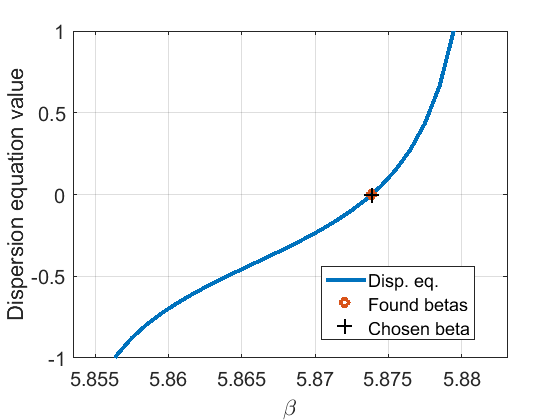

clear all;clc;close all;
a = 11/2; %Core radius in [\mu m]
b = 125/2; %Cladding radius in [\mu m]
nclad = 1.4440;
ncore = 1.4513;DELTA=(ncore-nclad)/ncore*100;%1.4513
lambda = 1.55; %Wavelength in [\mu m]
LP_type = [0,1];

[E_comp, H_comp, r_s, fi_s] = ModeSolver(lambda, a, b, 1, LP_type ...
    , 0, [ncore nclad], "LP");

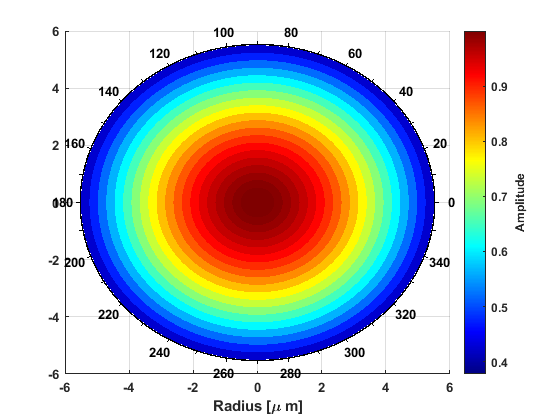


PlotMode(E_comp, H_comp, r_s, fi_s, a, b, "core");